clear
imageDatasetPath = fullfile('Img');
imds = imageDatastore(imageDatasetPath, 'IncludeSubfolders', true, 'LabelSource','foldernames');

[imdsTrain,imdsValidation] = splitEachLabel(imds, 0.7, 'randomize');

I = imread('smallDataSetImg\down\0a7c2a8d_nohash_0.png');
imagesize = size(I);

numClasses = countEachLabel(imdsTrain);
numClasses = height(numClasses);

layers = [
    imageInputLayer(imagesize)
    convolution2dLayer(8,20,'Padding',"same")
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
    ];

options = trainingOptions('sgdm', ...
    'MaxEpochs',5, ...
    'Shuffle',"every-epoch",...
    "Plots",'training-progress',...
    "Verbose",false,...
    'ValidationData',imdsValidation);

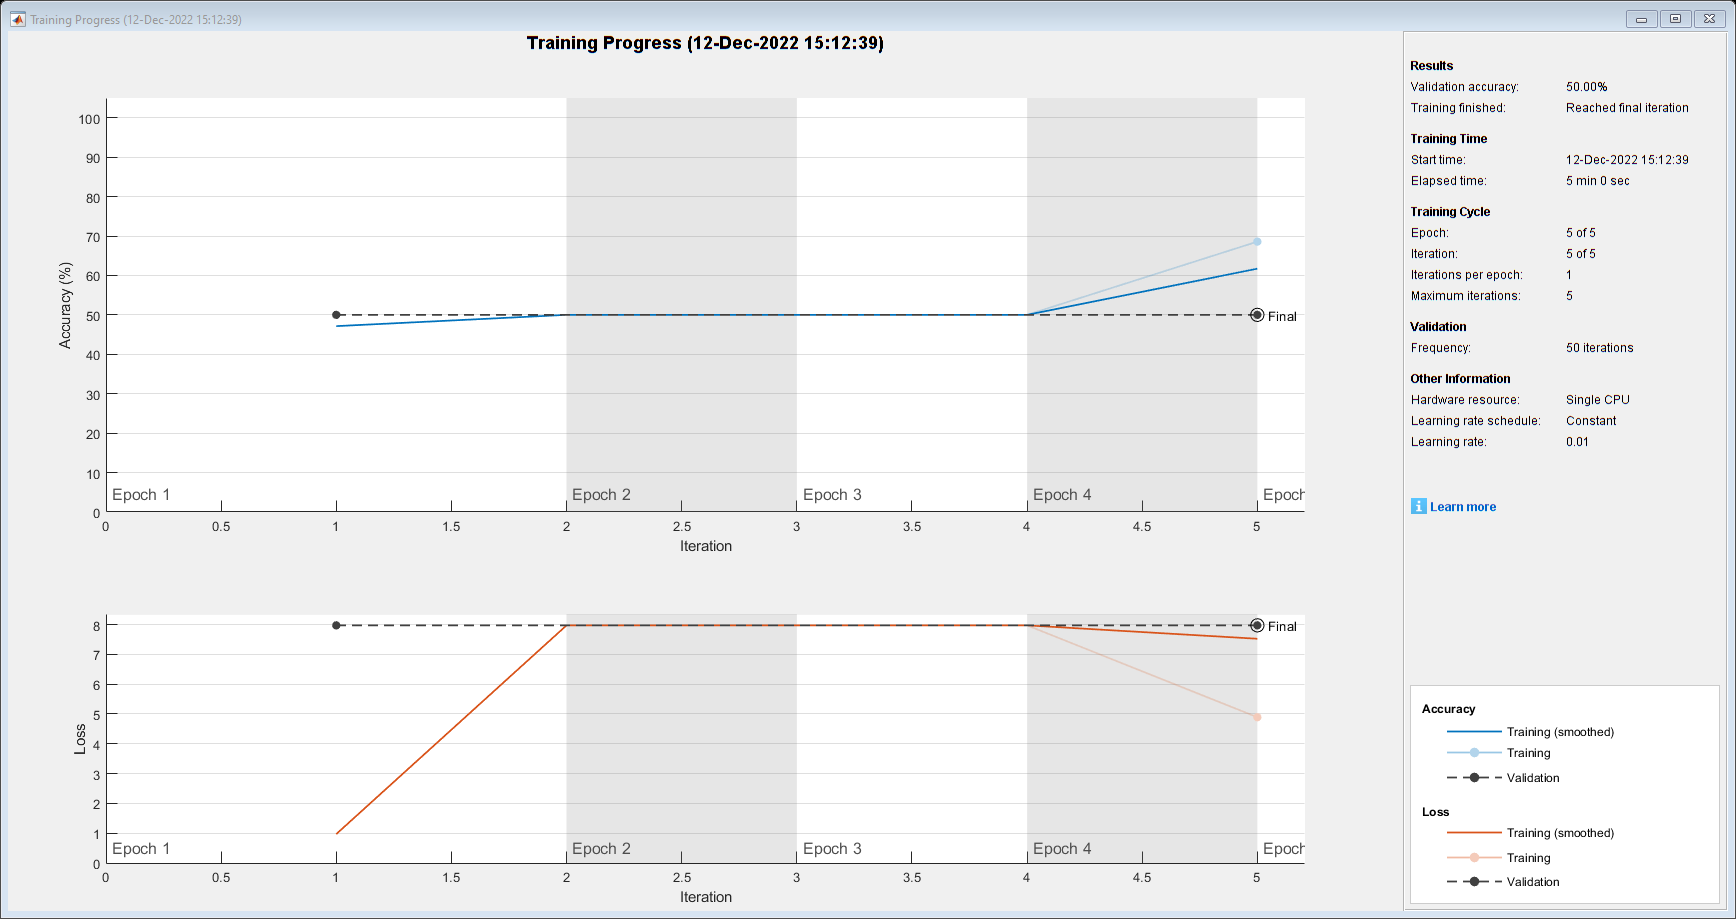

net = trainNetwork(imdsTrain, layers, options);

Pred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(Pred == YValidation)/numel(YValidation)

accuracy = 0.5000